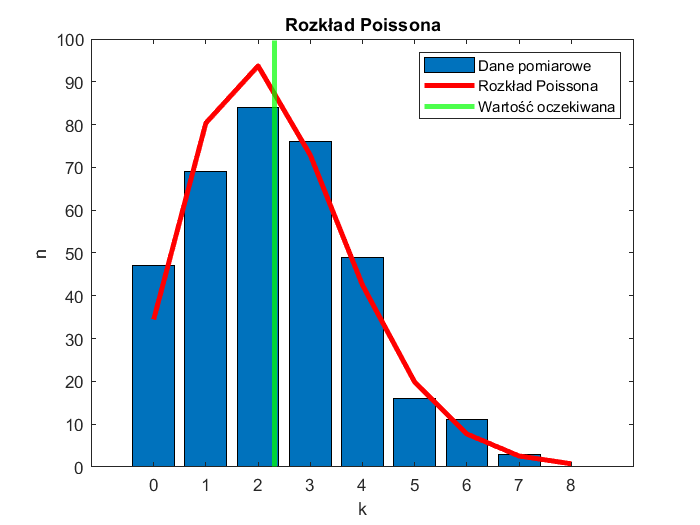

k=[0,1,2,3,4,5,6,7,8];
n_k=[47 ,69, 84 ,76 ,49 ,16 ,11, 3 ,0];


lambda = sum(n_k/sum(n_k).*k); 
f = @(k) (lambda.^k)*exp(-lambda)./ factorial(k);
suma = sum(n_k);
wartosc_oczekiwana=trapz(k,k.*f(k));
bar(k, n_k);
hold on;
ylabel('n');
xlabel('k');
%Dopasowana funkcja Poissona
plot(k, suma*f(k), 'r', 'Linewidth',3)
hold on;
xline(wartosc_oczekiwana,'g' ,'Linewidth',3);
hold on;
title('Rozkład Poissona');
legend('Dane pomiarowe','Rozkład Poissona',"Wartość oczekiwana");


%ilość stopni swobody to ilość pomiarów - liczba parametrów - 1
d = length(n_k) -1 -1 -1 ;%ostanie -1 wynika z tego ze dla tego parametru nie ma juz zandych wartosic czyli binów jest 8
poisson = suma*f(k); 
stala1=n_k-poisson;
stala1=stala1(1:8); % nie liczmy ostaniego pomiaru
poisson=poisson(1:8); % nie liczmy ostaniego pomiaru
chi2 =sum(stala1.^2./poisson);
poziom_istotnosci_p = 0.01; % Poziom istotności
critical_value0 = chi2inv(1 - poziom_istotnosci_p, d); % Wartość krytyczna
if critical_value0 > chi2
    disp('Na poziomie istotności 0.01 możemy przyjąć hipoteze że dane są opisane rozkładem Poissona.');
end

Na poziomie istotności 0.01 możemy przyjąć hipoteze że dane są opisane rozkładem Poissona.




%adanie 8.4
%rokład jednostajny 1/(b-a) 
a=0;
b=7;
for i = 1:9
g(i)=1/(b-a);
end
jendostajny=suma*g;
stala2=n_k-jendostajny;
chi_12 = sum(stala2.^2./jendostajny);
df = length(k) - 1 -1-1 ;
alpha = 0.01; % Poziom istotności
critical_value = chi2inv(1 - alpha, df); % Wartość krytyczna
if critical_value < chi_12
    disp('Na poziomie istotności 0.01 nie możemy przyjąć hipotezy że dane są opisane rozkładem jednostajnym.');
end

Na poziomie istotności 0.01 nie możemy przyjąć hipotezy że dane są opisane rozkładem jednostajnym.
